data = readtable('E:\New\DOCUMENTS\Projects\kone\projects\2023 L400 FYP\database\FYP\FYP\RF\P 1\Trial 2\right_foot.txt');

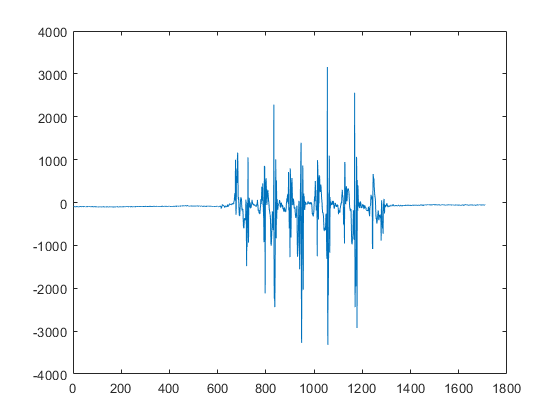

plot(data.Acc_X);

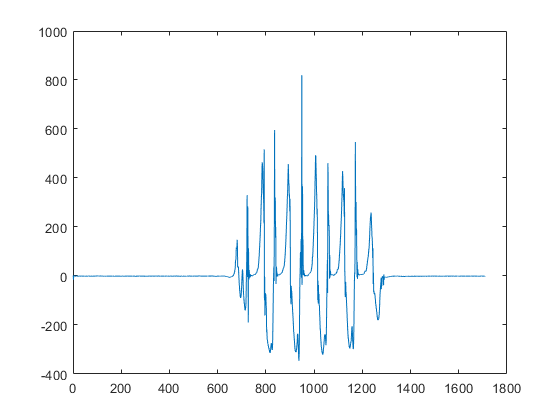

plot(data.Gyro_X);

newData=data(:,["Acc_X","Acc_Y","Acc_Z","Gyro_X","Gyro_Y","Gyro_Z","Magn_X","Magn_Y",...
    "Magn_Z"]);

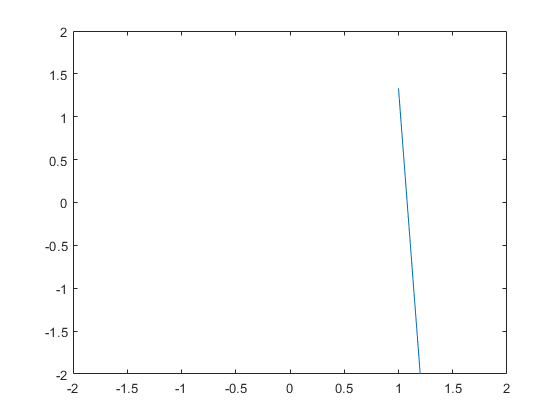

% Create sensor data struct
sensorData.Acceleration = struct('Acc_X', [], 'Acc_Y', [], 'Acc_Z', []);   % Initialize empty arrays for Acceleration
sensorData.AngularVelocity = struct('Gyro_X', [], 'Gyro_Y', [], 'Gyro_Z', []);  % Initialize empty arrays for AngularVelocity
sensorData.MagneticField = struct('Magn_X', [], 'Magn_Y', [], 'Magn_Z', []);  % Initialize empty arrays for MagneticField

% Assign data to the fields
sensorData.Acceleration.Acc_X = data.Acc_X;   % Replace rand(1600, 1) with your actual data
sensorData.Acceleration.Acc_Y = data.Acc_Y;   % Replace rand(1600, 1) with your actual data
sensorData.Acceleration.Acc_Z = data.Acc_Z;   % Replace rand(1600, 1) with your actual data

sensorData.AngularVelocity.Gyro_X = data.Gyro_X;  % Replace rand(1600, 1) with your actual data
sensorData.AngularVelocity.Gyro_Y = data.Gyro_Y;  % Replace rand(1600, 1) with your actual data
sensorData.AngularVelocity.Gyro_Z = data.Gyro_Z;  % Replace rand(1600, 1) with your actual data

sensorData.MagneticField.Magn_X = data.Magn_X;  % Replace rand(1600, 1) with your actual data
sensorData.MagneticField.Magn_Y = data.Magn_Y;  % Replace rand(1600, 1) with your actual data
sensorData.MagneticField.Magn_Z = data.Magn_Z;  % Replace rand(1600, 1) with your actual data
%pp = poseplot;

xlim([-2.00 2.00])
ylim([-2.00 2.00])
zlim([-2.00 2.00])

% Create Id struct
Id.Fs = 100;                      % Set the initial value for Fs (sampling rate)
Id.sensorData = sensorData;    % Assign the sensorData struct to the field in Id


cfilt = complementaryFilter('SampleRate', Id.Fs);

eulerAngles = zeros(size(Id.sensorData.Acceleration.Acc_X, 1), 3); % Initialize array to store Euler angles

for ii = 1:size(Id.sensorData.Acceleration.Acc_X, 1)
    acc = [Id.sensorData.Acceleration.Acc_X(ii), Id.sensorData.Acceleration.Acc_Y(ii), Id.sensorData.Acceleration.Acc_Z(ii)];
    gyro = [Id.sensorData.AngularVelocity.Gyro_X(ii), Id.sensorData.AngularVelocity.Gyro_Y(ii), Id.sensorData.AngularVelocity.Gyro_Z(ii)];
    mag = [Id.sensorData.MagneticField.Magn_X(ii), Id.sensorData.MagneticField.Magn_Y(ii), Id.sensorData.MagneticField.Magn_Z(ii)];

    qahrs = cfilt(acc, gyro, mag);
%    set(pp, 'Orientation', qahrs);

xlim([-2.00 2.00])
ylim([-2.00 2.00])
zlim([-2.00 2.00])
    drawnow limitrate;

    % Compute Euler angles (roll, pitch, yaw) from quaternion
    R = quat2rotm(qahrs);
    roll = atan2(R(3, 2), R(3, 3));
    pitch = atan2(-R(3, 1), sqrt(R(3, 2)^2 + R(3, 3)^2));
    yaw = atan2(R(2, 1), R(1, 1));

    % Convert angles to degrees if needed
    roll_deg = rad2deg(roll);
    pitch_deg = rad2deg(pitch);
    yaw_deg = rad2deg(yaw);

    eulerAngles(ii, :) = [roll_deg, pitch_deg, yaw_deg];
end


% eulerAngles now contains the computed Euler angles for each iteration
